im=imread('building2.jpg'); 
% im=imresize(im,0.25);
img=rgb2gray(im);


1) Calculate the matrices Ix and Iy , the partial derivatives of I(x,y)  

%Compute Ix & Iy
Gy=[-1,0,1;-2,0,2;-1,0,1];
Gx=[1,2,1;0,0,0;-1,-2,-1];
disp(Gx)

     1     2     1
     0     0     0
    -1    -2    -1



disp(Gy)

    -1     0     1
    -2     0     2
    -1     0     1



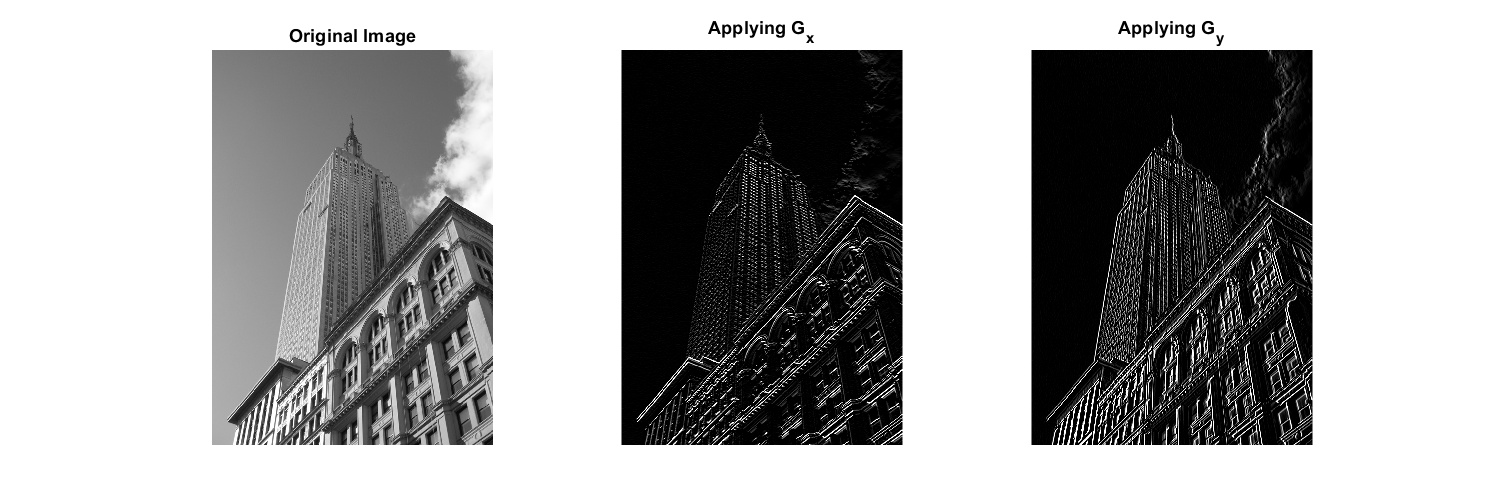


% Ix=conv2(img,Gx,'same');
% Iy=conv2(img,Gy,'same');
Ix=imfilter(img,Gx,'symmetric');
Iy=imfilter(img,Gy,'symmetric');
Ix=double(Ix);Iy=double(Iy);

figure('Position',[0,0,1200,400]);
tiledlayout(1,3,'TileSpacing',"none");
nexttile;imshow(img); title('Original Image');
nexttile;imshow(rescale(Ix,0,1));title('Applying G_x');
nexttile;imshow(rescale(Iy,0,1));title('Applying G_y');

2) Compute Ix^2, Iy^2, (Ix*Iy)

Ixx=Ix.*Ix;
Iyy=Iy.*Iy;
Ixy=Ix.*Iy;


Show these matrices as grey level images and combined in a RGB 

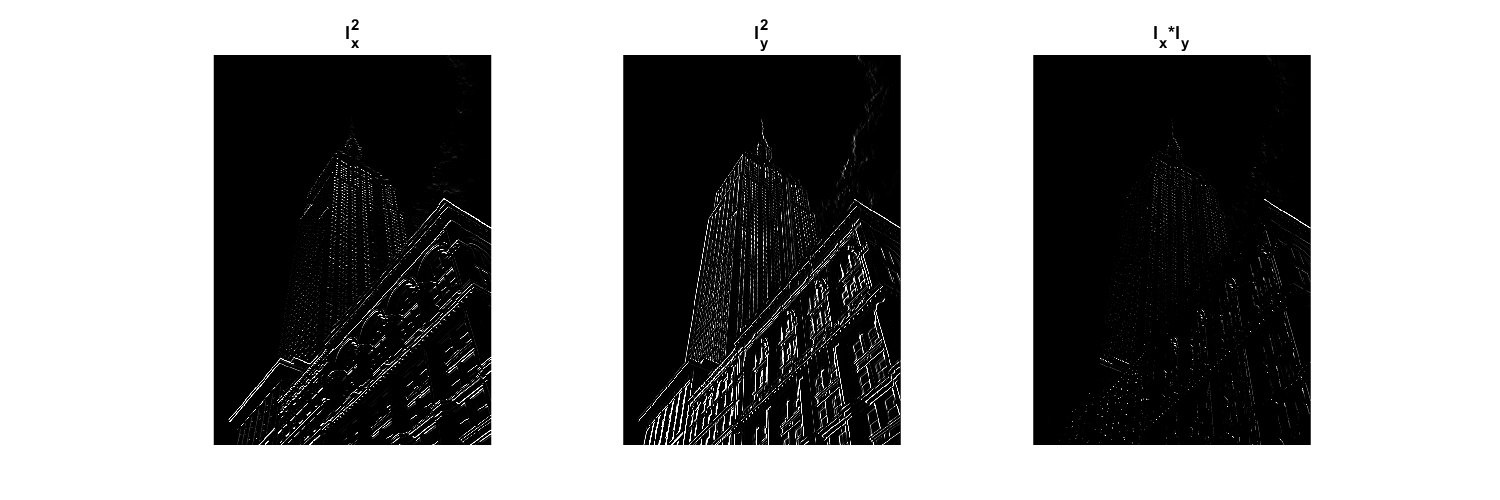

figure('Position',[0,0,1200,400]);
tiledlayout(1,3,'TileSpacing',"none");
nexttile;imshow(rescale(Ixx,0,1)); title('I_x^2');
nexttile;imshow(rescale(Iyy,0,1));title('I_y^2');
nexttile;imshow(rescale(Ixy,0,1));title('I_x*I_y');

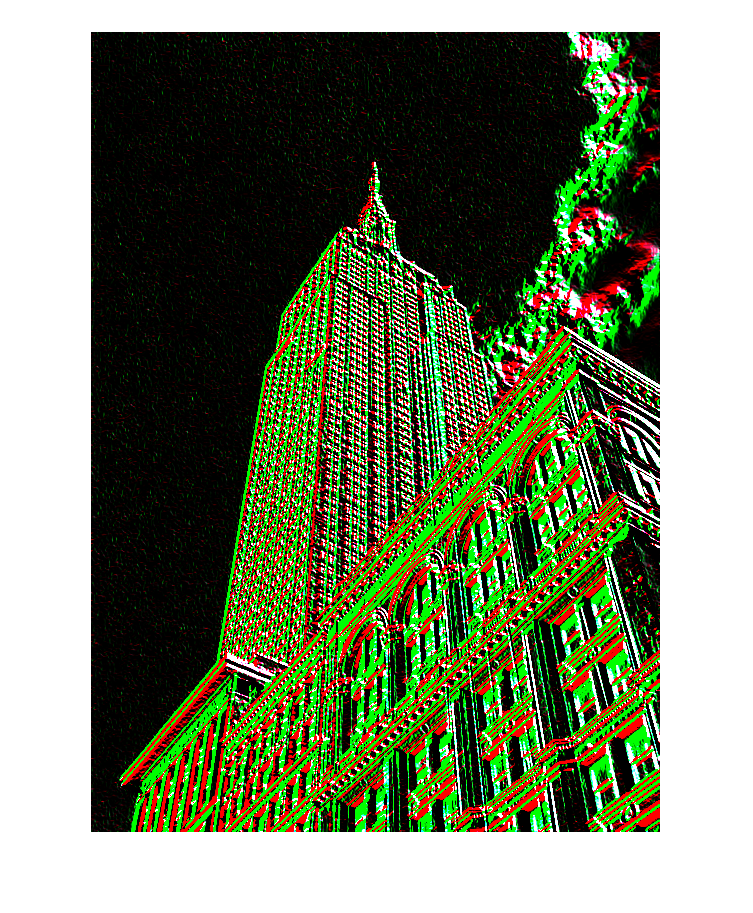

combRGB=uint8(zeros(size(im)));
combRGB(:,:,1)=Ixx;
combRGB(:,:,2)=Iyy;
combRGB(:,:,3)=abs(Ixy);
figure; imshow(combRGB);

4) Average the results with a Gaussian filter  and build the A matrix for every pixel of the original image.  

sigma=1;
Ixxg=imgaussfilt(Ixx,sigma);
Iyyg=imgaussfilt(Iyy,sigma);
Ixyg=imgaussfilt(Ixy,sigma);
%A matrix for every pixel would be
%A=[Ixxg(r,c),Ixyg(r,c);Ixyg(r,c),Iyyg(r,c)]

5 )For every pixel calculate the function Mc, from *det(A) *and *trace(A)*.  

k=0.1;
Mcim=zeros(size(img));
for r=1:size(im,1)
    for c=1:size(im,2)
        A=[Ixxg(r,c),Ixyg(r,c);Ixyg(r,c),Iyyg(r,c)];
        Mc=det(A)-k*trace(A)^2;
        Mcim(r,c)=Mc;
    end
end

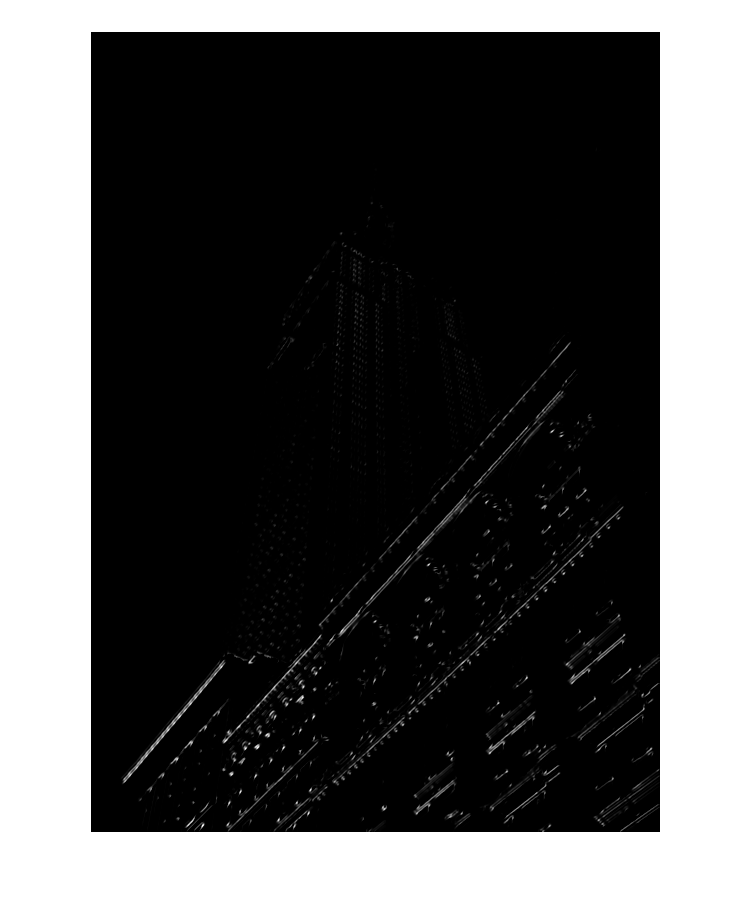

Mcim=(Mcim>0).*Mcim; %Filter the non positive results
Mcim=rescale(Mcim,0,1); %Reescale

figure; imshow(Mcim);

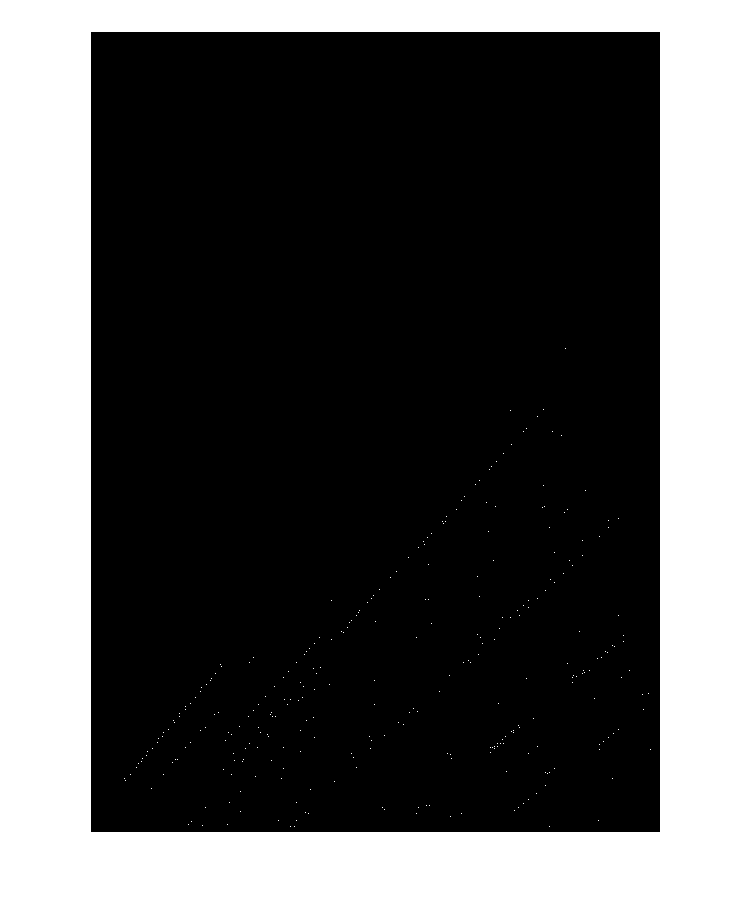


E=imregionalmax(Mcim); %Function from the computer vision toolbox to found maxima
E=E.*double(Mcim>0.5); %Only use those maxima grater than a given threshold
imshow(E); %Singular points as binary image

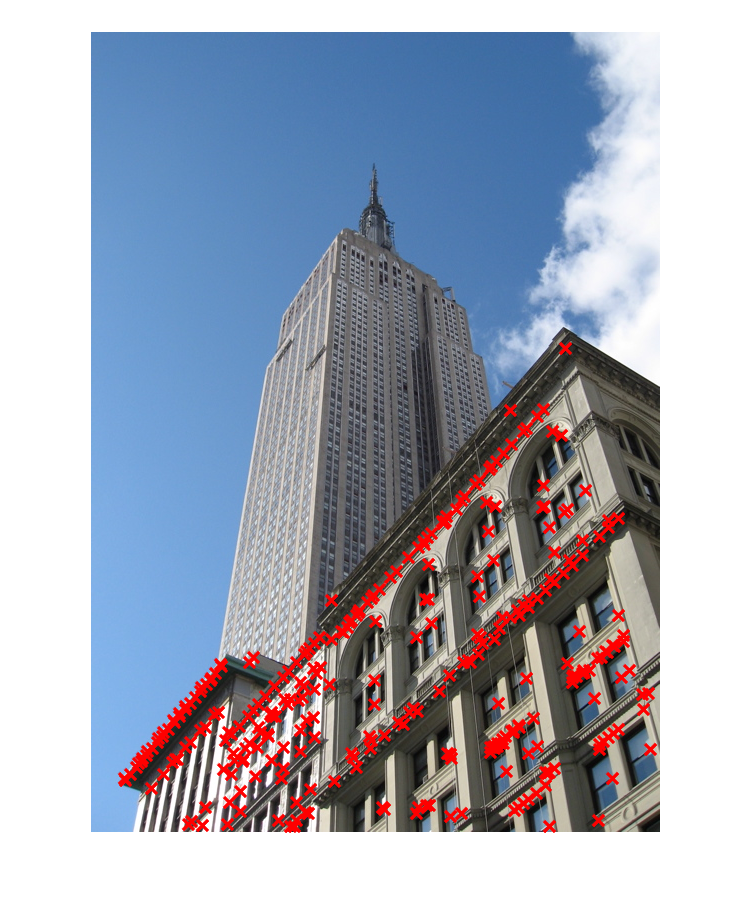

[y,x]=find(E==1); %Coordinates of the points

figure; imshow(im,[]);
hold on;
scatter(x,y,90,'rx','LineWidth',2);

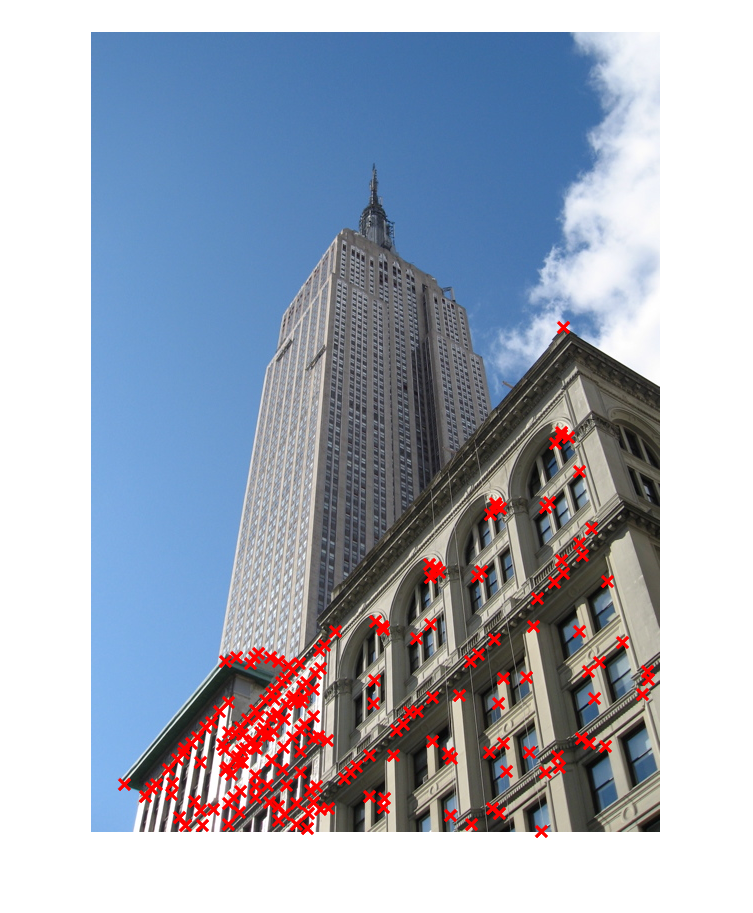

c=corner(img);
figure; imshow(im); hold on;
scatter(c(:,1),c(:,2),90,'rx','LineWidth',2);

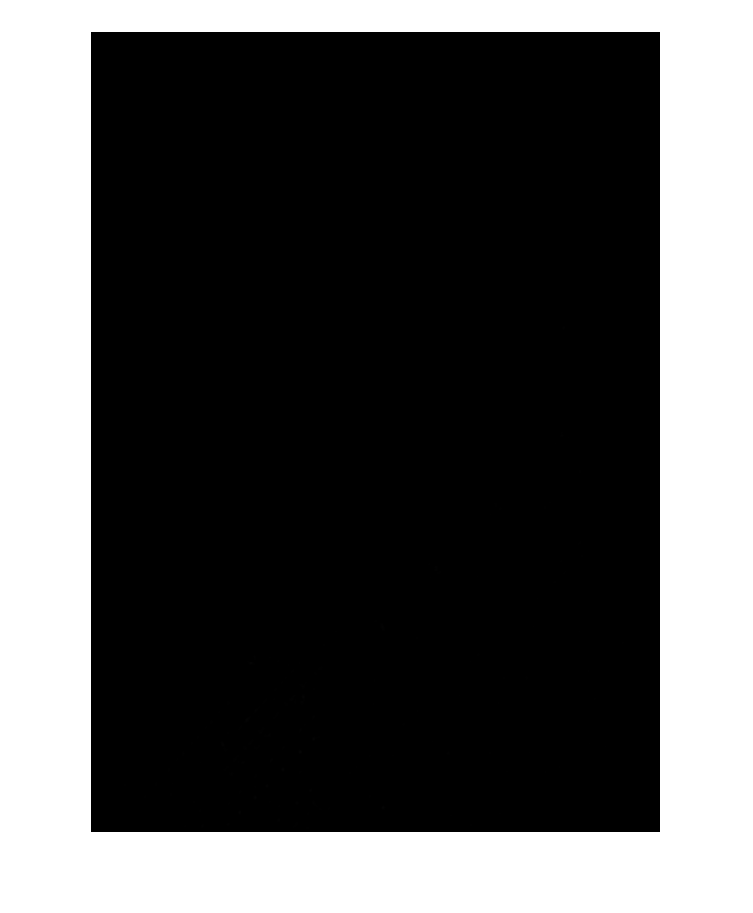


cm=cornermetric(img);
figure; imshow(cm);